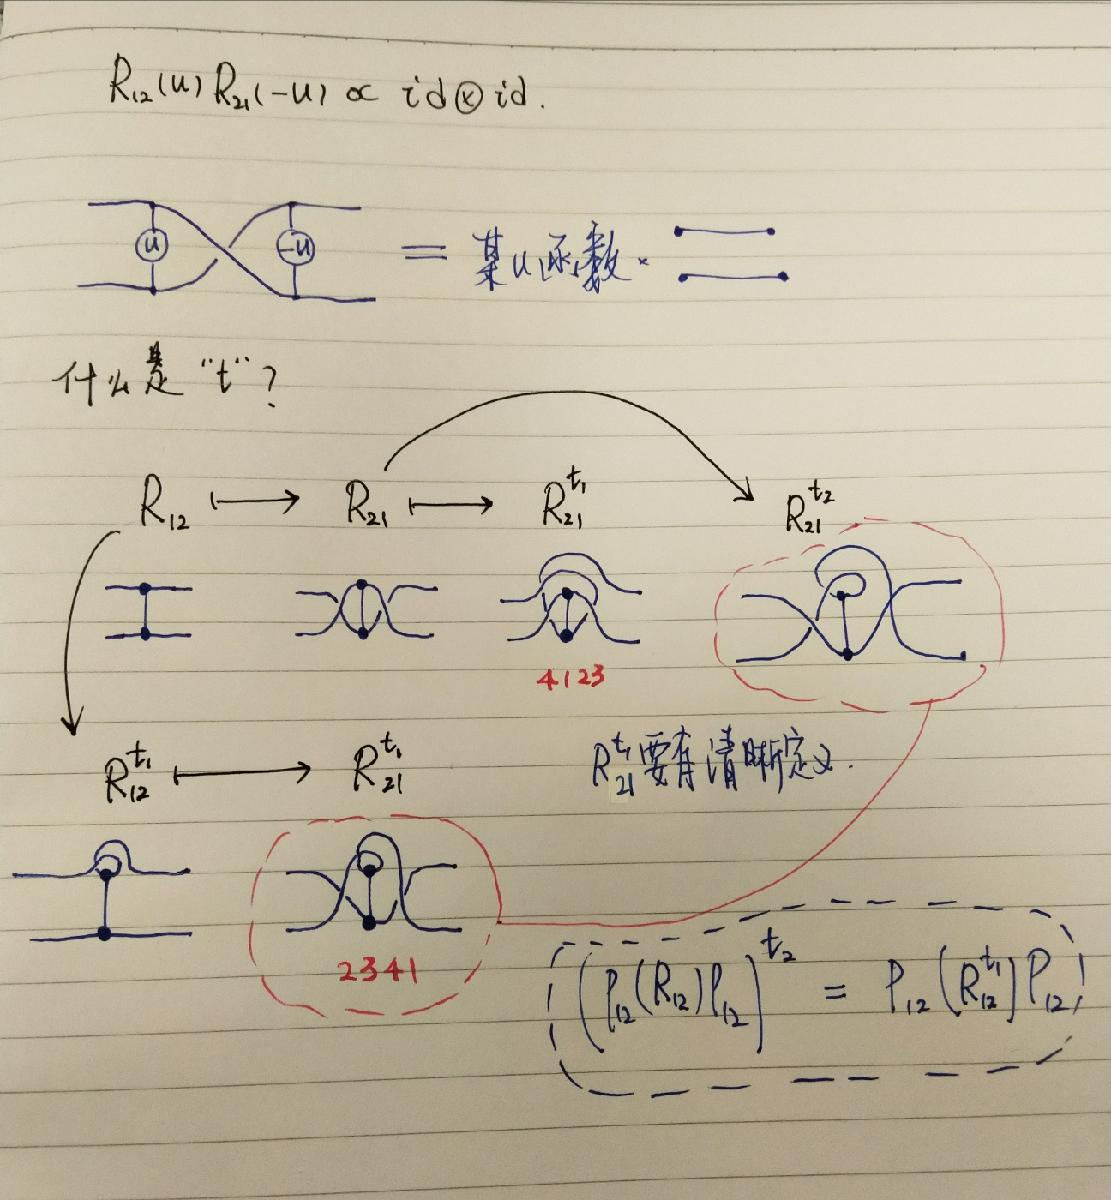

m4id=zeros(2,2,2,2);
m4id(1,1,1,1)=1;
m4id(1,2,1,2)=1;
m4id(2,1,2,1)=1;
m4id(2,2,2,2)=1;

m4p=zeros(2,2,2,2);
m4p(1,1,1,1)=1;
m4p(1,2,2,1)=1;
m4p(2,1,1,2)=1;
m4p(2,2,2,2)=1;

m4q=zeros(2,2,2,2);
m4q(1,1,1,1)=1;
m4q(2,2,2,2)=1;
m4q(1,1,2,2)=1;
m4q(2,2,1,1)=1;

m4Q=zeros(2,2,2,2);
m4Q(1,2,2,1)=1;
m4Q(2,1,1,2)=1;

m2sy=[0,-1j;1j,0];
m2id=[1,0;0,1];

m4sy1=fn_contract(m2sy,3,3,reshape(m2id,1,2,2),3,1);
m4sy1=permute(m4sy1,[1,3,2,4]);
m2sy1=reshape(m4sy1,4,4);
m4sy2=fn_contract(m2id,3,3,reshape(m2sy,1,2,2),3,1);
m4sy2=permute(m4sy2,[1,3,2,4]);
m2sy2=reshape(m4sy2,4,4);

m2p=reshape(m4p,4,4);
m2id=reshape(m4id,4,4);

syms fm4R(x);
syms fR12(x);
syms x;
syms f(x);
f(x)=x;
fm4R(x)=f(x)*m4id+1*m4p;
% fm4R(x)=floor(rand(2,2,2,2)*10);
fR12(x)=fm4R(x);
tm=fn_contract(m4p,4,[3,4],fR12(x),4,[1,2]);
syms fRhat12(x);
fRhat12(x)=tm;
reshape(fR12(lambda),4,4)
reshape(permute(fR12(lambda),[2,3,1,4]),4,4)
syms fRtest(x);
fRtest(x)=permute(fR12(lambda),[2,3,1,4]);
reshape(fRtest(lambda),4,4)
tm=fn_contract(fRtest(lambda),4,3,m2sy,2,1);
tm=permute(tm,[1,2,4,3]);
tm=fn_contract(tm,4,[3,4],fRtest(lambda),4,[1,2]);
tm=fn_contract(tm,4,4,m2sy,2,1);
reshape(tm,4,4)
reshape(fRhat12(lambda),4,4)
reshape(fn_contract(fRhat12(lambda),4,[3,4],fRhat12(-lambda),4,[1,2]),4,4)
reshape(fn_contract(fR12(lambda),4,[3,4],fR12(-lambda),4,[1,2]),4,4)

simplify(reshape(fm4R(lambda),4,4)*reshape(fm4R(-lambda),4,4))

reshape(fm4R(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

apply T1

tm2=fn_contract(m4p,4,[1,2],fm4R(x),4,[1,3]);
tm2=permute(tm2,[1,3,2,4]);
syms fR12t1(x);
fR12t1(x)=tm2;
reshape(fR12t1(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 1\\ 0 & \lambda & 0 & 0\\ 0 & 0 & \lambda & 0\\ 1 & 0 & 0 & \lambda +1 \end{array}\right)$$

 permute 12

tm2=fn_contract(m4p,4,[3,4],fm4R(x),4,[1,2]);
tm2=fn_contract(tm2,4,[3,4],m4p,4,[1,2]);
syms fR21(x);
fR21(x)=tm2;
reshape(fR21(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

T1 * permute12

tm2=fn_contract(m4p,4,[1,2],fR21(x),4,[1,3]);
tm2=permute(tm2,[1,3,2,4]);
syms fR21t1(x);
fR21t1(x)=tm2;
reshape(fR21t1(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 1\\ 0 & \lambda & 0 & 0\\ 0 & 0 & \lambda & 0\\ 1 & 0 & 0 & \lambda +1 \end{array}\right)$$

permute 12 * T1

tm2=fn_contract(m4p,4,[3,4],fR12t1(x),4,[1,2]);
tm2=fn_contract(tm2,4,[3,4],m4p,4,[1,2]);
syms fR21t1prime(x);
fR21t1prime(x)=tm2;
reshape(fR21t1prime(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 1\\ 0 & \lambda & 0 & 0\\ 0 & 0 & \lambda & 0\\ 1 & 0 & 0 & \lambda +1 \end{array}\right)$$

tm2=permute(fR12(x),[3,4,1,2]);
syms fR12t1t2(x);
fR12t1t2(x)=tm2;

**In this case the fR12t1 is equal to fR21tiprime**

syms u;
reshape(fR12(u),4,4)*reshape(fR12(-u),4,4)

$$ans = \left(\begin{array}{cccc} -\left(u-1\right)\,\left(u+1\right) & 0 & 0 & 0\\ 0 & 1-u^{2} & 0 & 0\\ 0 & 0 & 1-u^{2} & 0\\ 0 & 0 & 0 & -\left(u-1\right)\,\left(u+1\right) \end{array}\right)$$

reshape(fR12(u),4,4)

$$ans = \left(\begin{array}{cccc} u+1 & 0 & 0 & 0\\ 0 & u & 1 & 0\\ 0 & 1 & u & 0\\ 0 & 0 & 0 & u+1 \end{array}\right)$$

reshape(fR21(u),4,4)

$$ans = \left(\begin{array}{cccc} u+1 & 0 & 0 & 0\\ 0 & u & 1 & 0\\ 0 & 1 & u & 0\\ 0 & 0 & 0 & u+1 \end{array}\right)$$

**1.5.4**

reshape(fR12(0),4,4)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

**1.5.5**

reshape(fR12(lambda),4,4)*reshape(fR21(-lambda),4,4)

$$ans = \left(\begin{array}{cccc} -\left(\lambda -1\right)\,\left(\lambda +1\right) & 0 & 0 & 0\\ 0 & 1-\lambda^{2} & 0 & 0\\ 0 & 0 & 1-\lambda^{2} & 0\\ 0 & 0 & 0 & -\left(\lambda -1\right)\,\left(\lambda +1\right) \end{array}\right)$$

**1.5.6**

reshape(fR12t1(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 1\\ 0 & \lambda & 0 & 0\\ 0 & 0 & \lambda & 0\\ 1 & 0 & 0 & \lambda +1 \end{array}\right)$$

reshape(permute(fR12(lambda),[3,2,1,4]),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 1\\ 0 & \lambda & 0 & 0\\ 0 & 0 & \lambda & 0\\ 1 & 0 & 0 & \lambda +1 \end{array}\right)$$

reshape(fR12(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

tm=fn_contract(m2sy,2,2,fR12t1(-1-lambda),4,2);
tm=permute(tm,[2,1,3,4]);
tm=fn_contract(tm,4,4,m2sy,2,1);
tm=-tm;
reshape(tm,4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

tm=fn_contract(m2sy,2,2,fR12t1(-1-lambda),4,1);
% tm=permute(tm,[2,1,4,3]);
tm=fn_contract(tm,4,3,m2sy,2,1);
permute(tm,[1,2,4,3]);
tm=-tm;
reshape(tm,4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & 1 & \lambda & 0\\ 0 & \lambda & 1 & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

reshape(u*m4id+m4q,4,4)

$$ans = \left(\begin{array}{cccc} u+1 & 0 & 0 & 1\\ 0 & u & 0 & 0\\ 0 & 0 & u & 0\\ 1 & 0 & 0 & u+1 \end{array}\right)$$

reshape(fR12t1(u),4,4)

$$ans = \left(\begin{array}{cccc} u+1 & 0 & 0 & 1\\ 0 & u & 0 & 0\\ 0 & 0 & u & 0\\ 1 & 0 & 0 & u+1 \end{array}\right)$$

## the above calculations shows that the formula in 1.5.6 are incorrect. the  sigmas should be sigma_2^y

syms theta;
syms mtest(x);
mtest(theta)=[cos(theta),sin(theta);-sin(theta),cos(theta)]

$$mtest(theta) = \left(\begin{array}{cc} \cos\left(\theta \right) & \sin\left(\theta \right)\\ -\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

tm=fn_contract(mtest(theta),2,2,fR12t1(-1-lambda),4,2);
tm=permute(tm,[2,1,4,3]);
tm=fn_contract(tm,4,3,mtest(-theta),2,1);
permute(tm,[1,2,4,3]);
tm=-tm;
reshape(tm,4,4)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{4} & -\cos\left(\theta \right)\,\sin\left(\theta \right) & \sigma_{1} & -{\cos\left(\theta \right)}^{2}\\ -\cos\left(\theta \right)\,\sin\left(\theta \right) & \sigma_{3} & {\sin\left(\theta \right)}^{2} & \sigma_{2}\\ \sigma_{1} & {\sin\left(\theta \right)}^{2} & \sigma_{3} & \cos\left(\theta \right)\,\sin\left(\theta \right)\\ -{\cos\left(\theta \right)}^{2} & \sigma_{2} & \cos\left(\theta \right)\,\sin\left(\theta \right) & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(\lambda +1\right)-\lambda \,\cos\left(\theta \right)\,\sin\left(\theta \right)\\ \sigma_{2}=\lambda \,\cos\left(\theta \right)\,\sin\left(\theta \right)-\cos\left(\theta \right)\,\sin\left(\theta \right)\,\left(\lambda +1\right)\\ \sigma_{3}=\left(\lambda +1\right)\,{\cos\left(\theta \right)}^{2}+\lambda \,{\sin\left(\theta \right)}^{2}\\ \sigma_{4}=\lambda \,{\cos\left(\theta \right)}^{2}+\left(\lambda +1\right)\,{\sin\left(\theta \right)}^{2} \end{array}$$

tm=fn_contract(m4id,4,3,m2sy,2,1);
tm=permute(tm,[1,2,4,3]);
tm=fn_contract(tm,4,4,m2sy,2,1);
reshape(tm,4,4)

ans =      0     0     0    -1
     0     0     1     0
     0     1     0     0
    -1     0     0     0

reshape(m4p-m4q,4,4)

ans =      0     0     0    -1
     0     0     1     0
     0     1     0     0
    -1     0     0     0

reshape(permute(m4p,[1,2,4,3]),4,4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1

tm=fn_contract(tm,4,4,[0,1;1,0],2,1);
reshape(tm,4,4)

ans =      0    -1     0     0
     1     0     0     0
     0     0     0     1
     0     0    -1     0

**1.5.7**

reshape(fR12(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

reshape(fR21(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

reshape(fR12t1(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 1\\ 0 & \lambda & 0 & 0\\ 0 & 0 & \lambda & 0\\ 1 & 0 & 0 & \lambda +1 \end{array}\right)$$

reshape(fR12t1t2(lambda),4,4)

$$ans = \left(\begin{array}{cccc} \lambda +1 & 0 & 0 & 0\\ 0 & \lambda & 1 & 0\\ 0 & 1 & \lambda & 0\\ 0 & 0 & 0 & \lambda +1 \end{array}\right)$$

**1.5.8**

**1.5.9**

**1.5.10**


reshape(fR12t1(lambda),4,4)*reshape(fR12t1(-lambda-2),4,4)

$$ans = \left(\begin{array}{cccc} 1-{\left(\lambda +1\right)}^{2} & 0 & 0 & 0\\ 0 & -\lambda \,\left(\lambda +2\right) & 0 & 0\\ 0 & 0 & -\lambda \,\left(\lambda +2\right) & 0\\ 0 & 0 & 0 & 1-{\left(\lambda +1\right)}^{2} \end{array}\right)$$

tm=fn_contract(fR12t1(lambda),4,[3,4],fR12t1(-lambda-2),4,[1,2]);
reshape(tm,4,4)

$$ans = \left(\begin{array}{cccc} 1-{\left(\lambda +1\right)}^{2} & 0 & 0 & 0\\ 0 & -\lambda \,\left(\lambda +2\right) & 0 & 0\\ 0 & 0 & -\lambda \,\left(\lambda +2\right) & 0\\ 0 & 0 & 0 & 1-{\left(\lambda +1\right)}^{2} \end{array}\right)$$

syms fm4R(x);
syms x;
syms f(x);
f(x)=x;
fm4R(x)=floor(10*rand(2,2,2,2));
reshape(fm4R(x),4,4)
simplify(reshape(fm4R(lambda),4,4)*reshape(fm4R(-lambda),4,4))



disp("hahahahahahahahahaha")
reshape(fm4R(lambda),4,4)

apply T1

tm2=fn_contract(m4p,4,[1,2],fm4R(lambda),4,[1,3]);
tm2=permute(tm2,[1,3,2,4]);
syms fR12t1(x);
fR12t1(x)=tm2;
reshape(fR12t1(lambda),4,4)

 permute 12

tm2=fn_contract(m4p,4,[3,4],fm4R(lambda),4,[1,2]);
tm2=fn_contract(tm2,4,[3,4],m4p,4,[1,2]);
syms fR21(x);
fR21(lambda)=tm2;
reshape(fR21(lambda),4,4)

T1 * permute12

tm2=fn_contract(m4p,4,[1,2],fR21(lambda),4,[1,3]);
tm2=permute(tm2,[1,3,2,4]);
syms fR21t1(x);
fR21t1(x)=tm2;
reshape(fR21t1(lambda),4,4)

permute 12 * T1

tm2=fn_contract(m4p,4,[3,4],fR12t1(lambda),4,[1,2]);
tm2=fn_contract(tm2,4,[3,4],m4p,4,[1,2]);
syms fR21t1prime(x);
fR21t1prime(x)=tm2;
reshape(fR21t1prime(lambda),4,4)

T2*permute12

tm2=fn_contract(m4p,4,[1,2],fR21(lambda),4,[2,4]);
tm2=permute(tm2,[3,1,4,2]);
syms fR12t2(x);
fR12t2(x)=tm2;
reshape(fR12t2(lambda),4,4)


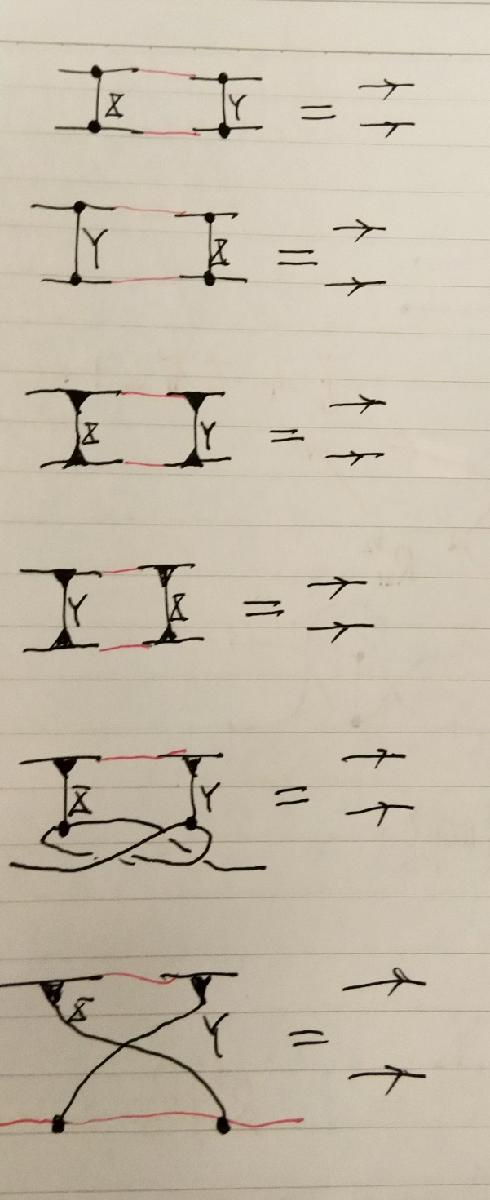

X=floor(10*rand(2,2,2,2));
m2X=reshape(X,4,4);
m2Y=inv(m2X);
Y=reshape(m2Y,[2,2,2,2]);

tm=fn_contract(m4p,4,[1,2],X,4,[1,3]);
tm=permute(tm,[1,3,2,4]);
Xt1=tm;
tm=fn_contract(m4p,4,[1,2],Y,4,[1,3]);
tm=permute(tm,[1,3,2,4]);
Yt1=tm;

tm=fn_contract(m4p,4,[1,2],X,4,[2,4]);
tm=permute(tm,[3,1,4,2]);
Xt2=tm;
tm=fn_contract(m4p,4,[1,2],Y,4,[2,4]);
tm=permute(tm,[3,1,4,2]);
Yt2=tm;

tm=fn_contract(m4p,4,[1,2],Xt2,4,[1,3]);
tm=permute(tm,[1,3,2,4]);
Xt1t2=tm;
tm=fn_contract(m4p,4,[1,2],Yt2,4,[1,3]);
tm=permute(tm,[1,3,2,4]);
Yt1t2=tm;

reshape(fn_contract(X,4,[3,4],Y,4,[1,2]),4,4)
reshape(permute(fn_contract(X,4,[1,4],Y,4,[3,2]),[3,1,2,4]),4,4)
reshape(fn_contract(Y,4,[3,4],X,4,[1,2]),4,4)
reshape(fn_contract(Xt1t2,4,[3,4],Yt1t2,4,[1,2]),4,4)
reshape(fn_contract(Yt1t2,4,[3,4],Xt1t2,4,[1,2]),4,4)
reshape(permute(fn_contract(Xt1,4,[3,2],Yt1,4,[1,4]),[1,3,4,2]),4,4)
